**9.1** 

Download the code to generate a filter bank of the Derivatives of the Gaussian, in other words: the Leung-Malik (LM) filter bank and display it in a figure:

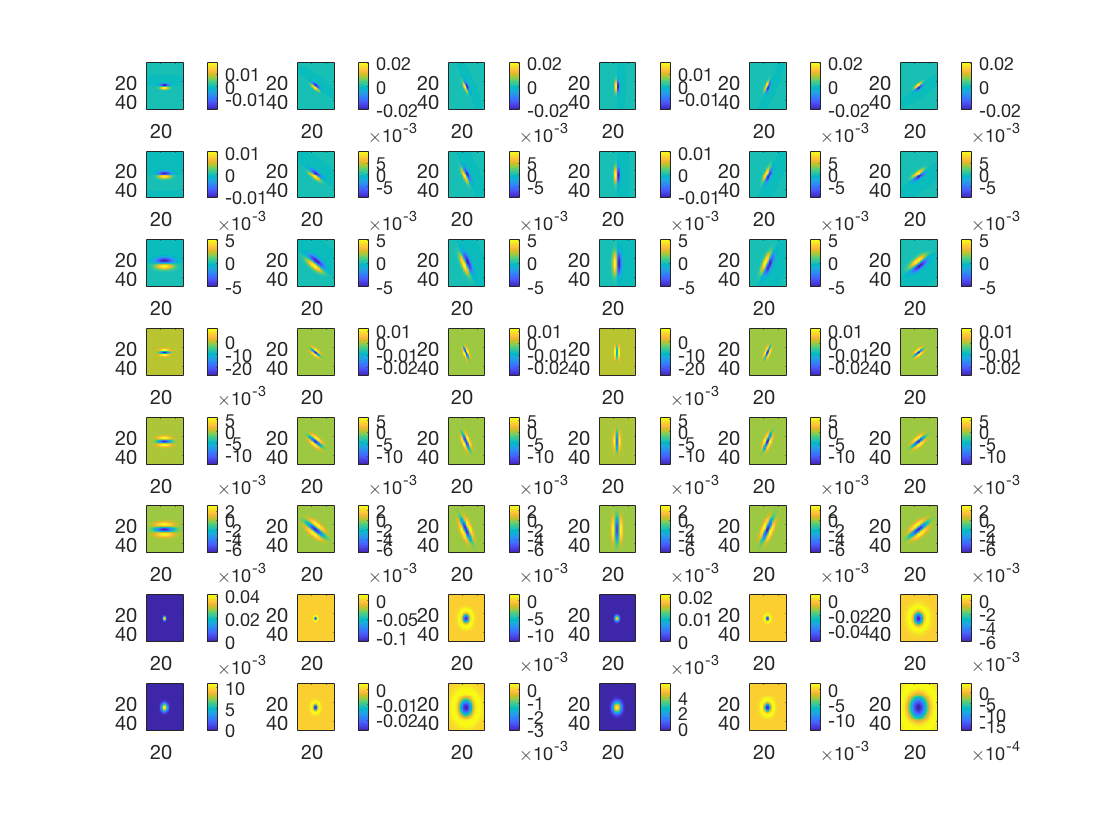

F=makeLMfilters(); % generate the filters
visualizeFilters(F);

Note: Look at the imagesc and colorbar commands. What do they do? What are the different filters? What values do they have?

`Imagesc` declares that the image that will be used for subplot k is the one located at the kth value of the 3rd dimension of matrix F (which contains the filter image data in the first two dimensions). This technique allows simple iterating and display of the different filter images for each subplot.

`Colorbar` simply displays a color scale beside the subplot of the filter image, it displays the current colormap and indicates the scale of the values of the data in the image.

**9.2**

Implement a function *getFeatures *that for an image builds its texture descriptors, where each element of the descriptor is the average result of the convolution of the image with the filters. 

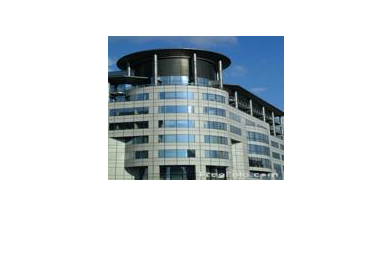

img = imread('texturesimages/buildings/buildings_1.jpg');
figure(2); hold off; imshow(img); 

features=getFeatures(img);
size(features)

ans =      1    48


How big is the descriptor? 

  The feature descriptor has 48 columns in size, each corresponding to the mean convolution value of the image processed by a different filter.

**9.3**

Write a *getClassFeatures *function that given a directory and an extension, read all images in the directory with the extension given, calculates their texture descriptors (using *getFeatures *of 9.1.2) and stores them in a matrix where each row corresponds to an image and each column to a feature. Apply this to build three matrices of texture descriptors corresponding to the 3 image directories.      

buildings = getClassFeatures('texturesimages/buildings','jpg');
forest = getClassFeatures('texturesimages/forest','jpg');
sunset = getClassFeatures('texturesimages/sunset','jpg');

**9.4**

Write a *visualizeFeatures *function to display in a plot a list of one or several features (eg [25, 41]) for images of the three directories using a different color for each directory (help *plot*). Define another function *visualizeFeatures3D *to display as 3D plots the three groups of images (corresponding to the 3 directories) using three specific features (eg. [25, 38, 41]. What does each axis correspond to in the 2D and 3D visualizations? 

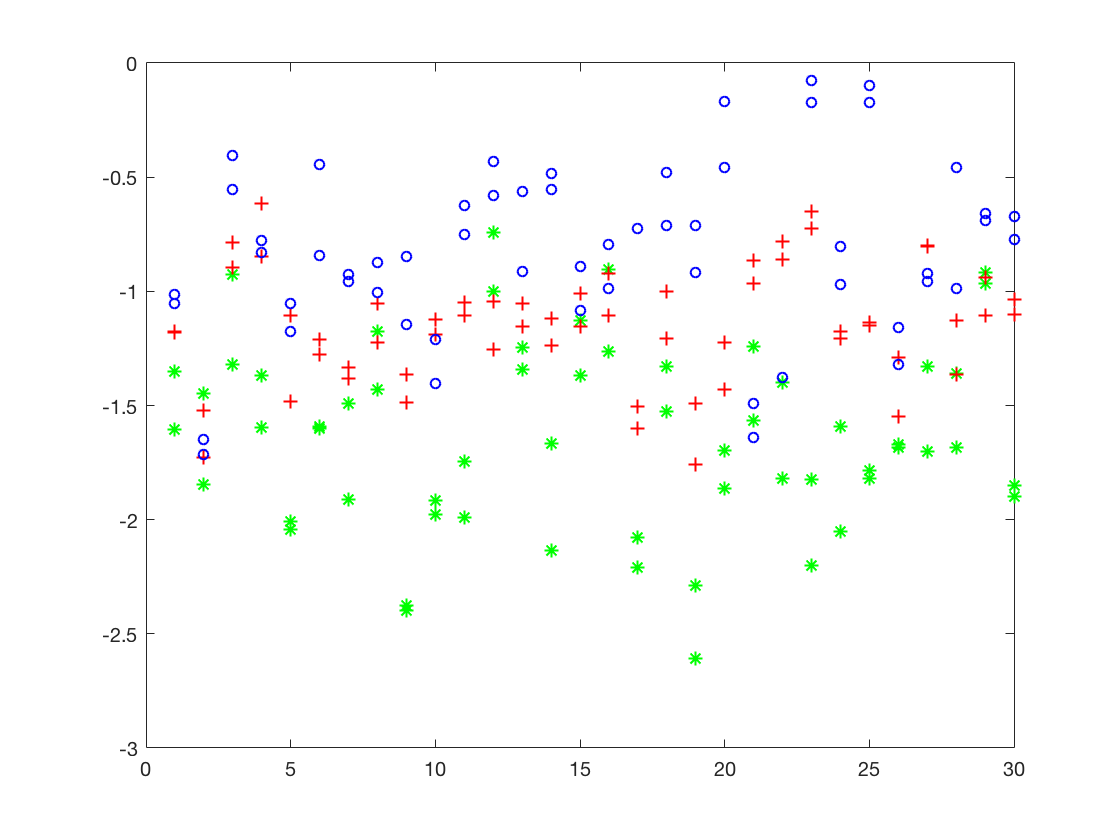

visualizeFeatures({buildings,forest,sunset}, {'g*','r+','bo'}, [41,25]);

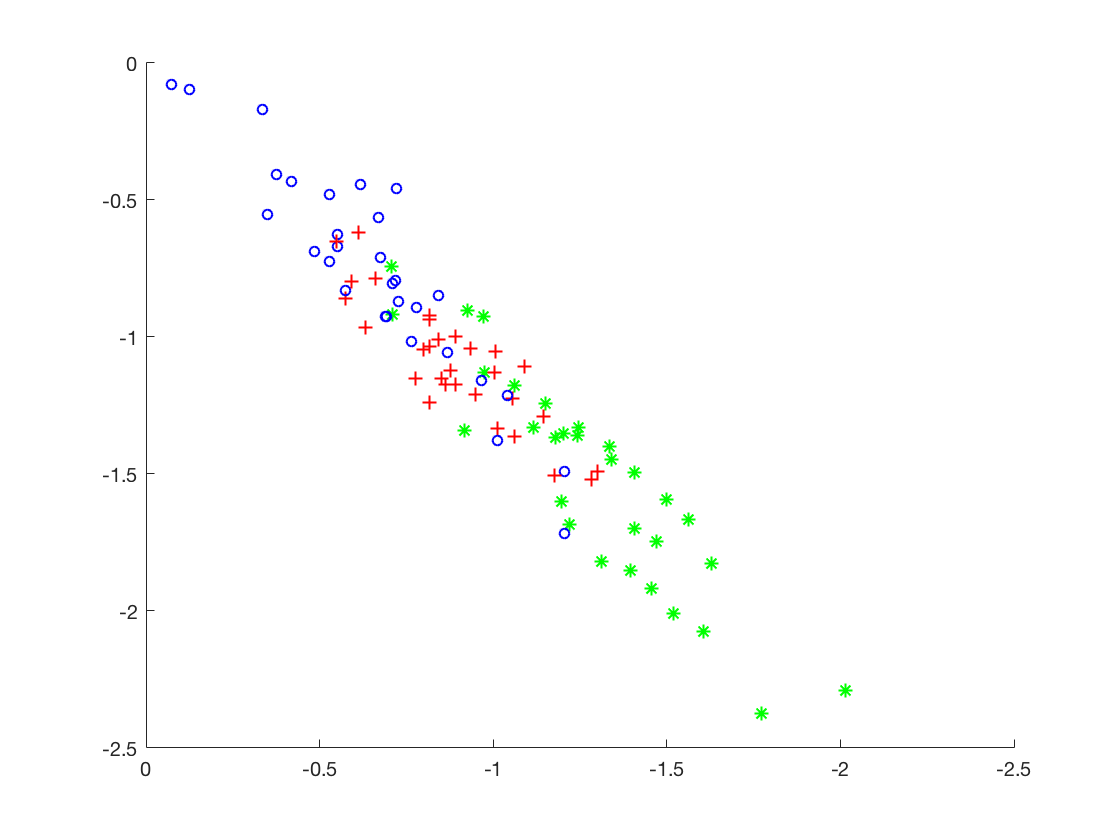

visualizeFeatures3D({buildings,forest,sunset}, {'g*','r+','bo'}, [25,38,41]);

view([-90.00 90.00])

What does each axis correspond to in the 2D and 3D visualizations?

2d:

x: image number

y: convolution value

3d:

x: feature1 convolution values,

y: feature2 convolution values,

z: feature3 convolution values

**9.5**

For each image of the three classes, write the function  retrieveKImages to retrieve and display the k (e.g. k = 9) most similar images as texture descriptors  (see Fig. 4).  Note: You can use the command knnsearch  

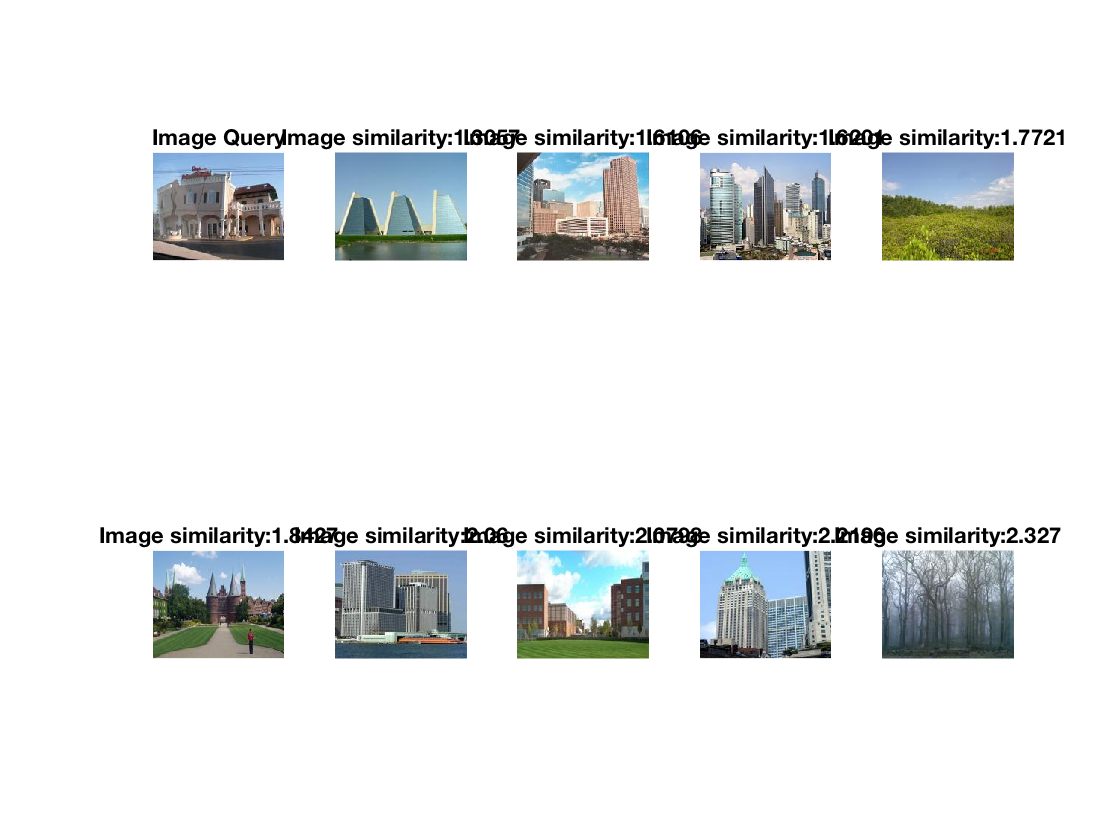

images = retrieveKImages(7, {'texturesimages/buildings', 'texturesimages/sunset', 'texturesimages/forest'}, 'jpg', 9, false);

Observe the result when the colour (r, g, b) is added to the texture features as additional features per image. What dimension will the feature space have if we add the colour? Observe what are the most discriminative features for each set of images first without using colour and after adding colour features. Discuss your observations on the performance of the algorithm and possible improvements.

images = 1×10 cell array
    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}    {144×176×3 uint8}


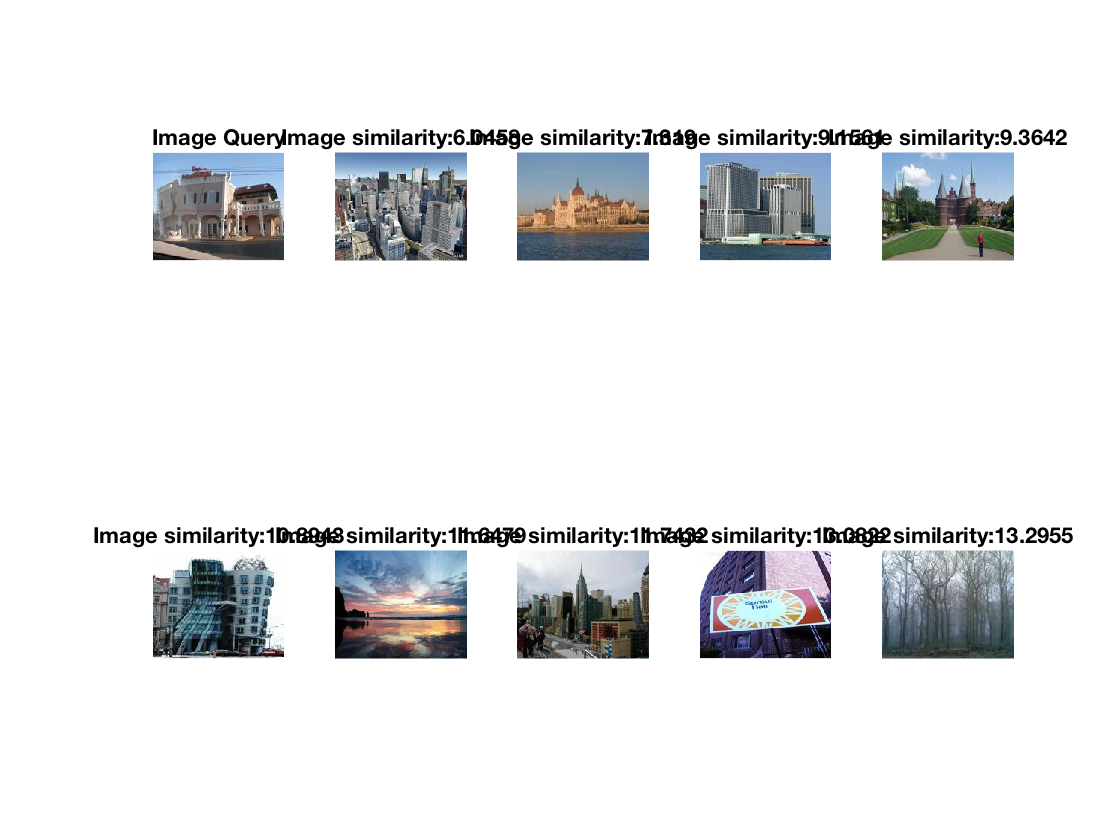

images = retrieveKImages(7, {'texturesimages/buildings', 'texturesimages/sunset', 'texturesimages/forest'}, 'jpg', 9, true)